# **demo09 of writeMesh**

**Set 'tolerance' when searching boundary node set**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Overview

By default, function printInp3d will automatically find boundary nodes of a 3d mesh. 'opt.tolerance' in function printInp3d could be very useful when searching boundary nodes.

'opt.tolerance' - Numeric value. It's the tolerance for coordinates when searching boundary node set (at max & min location). Sub-routine in function printInp3d will automatically find extrema for x y z coordinates in the mesh. Those surface nodes with coordinate satisfy **|coordinate - extrema|< tolerance** will be considered as boundary node set (at max & min location). 

Default value of 'opt.tolerance': 1E-10

## Example 1

### Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 350; height = 350;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

### Load mesh

Let's load the mesh data from "mesh_data_4.mat"

load("mesh_data_4.mat")

We will see 3 variables in the workspace: vert, ele, tnum

Use function plotMeshes3d to plot 3d mesh.

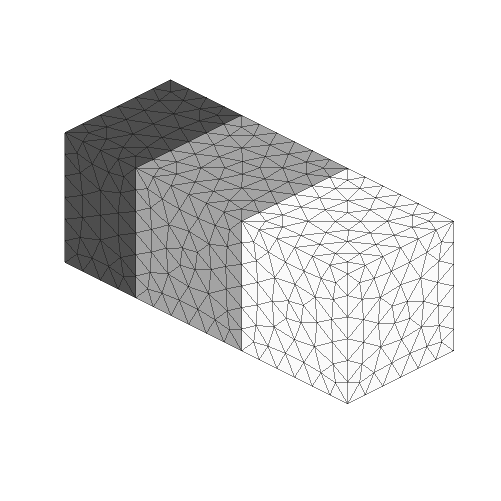

plotMeshes3d( vert, ele, tnum );

### Display boundary nodes

By default, function printInp3d will automatically search and export node sets at the boundary. 

Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been correctly found. 

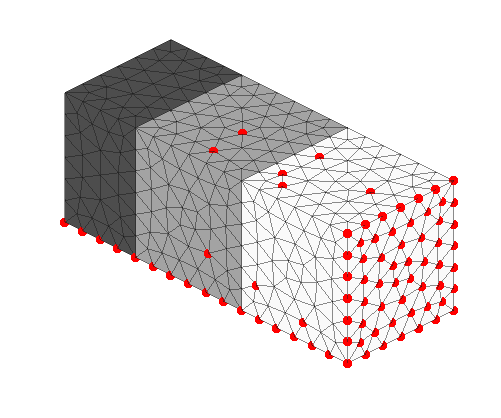

tolerance = 1E-20;
markerSize = 15;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

We noticed that some nodes are missing. So we can try a bigger tolerance.

### Change 'tolerance'

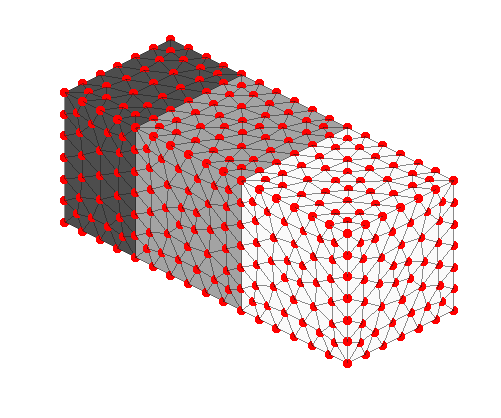

tolerance = 1E-10;
markerSize = 15;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

Awesome. It's much better.

### Display node at 'x' boundary

To further validate the result, we can display boundary nodes at x min and x max.

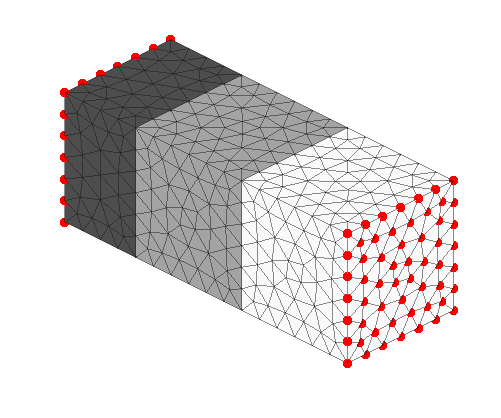

tolerance = 1E-10;
markerSize = 15;
plane = 'x';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Display node at 'y' boundary

To further validate the result, we can display boundary nodes at y min and y max.

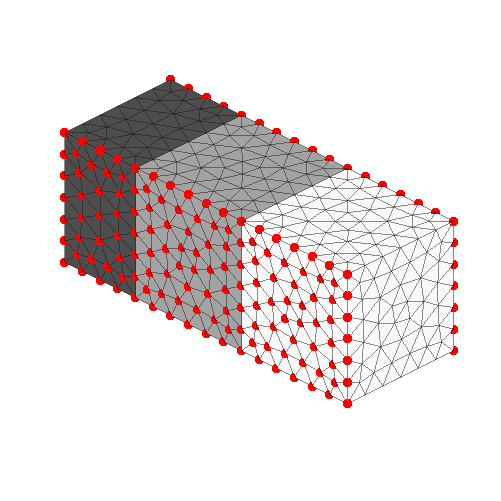

tolerance = 1E-10;
markerSize = 15;
plane = 'y';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Display node at 'z' boundary

To further validate the result, we can display boundary nodes at z min and z max.

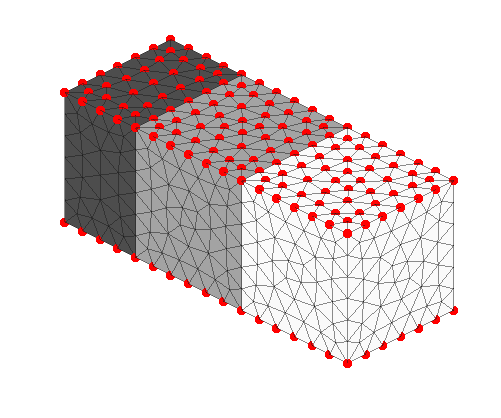

tolerance = 1E-10;
markerSize = 15;
plane = 'z';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

When using function printInp3d, we can specify 'opt.tolerance' explicitly. 

Default value of 'opt.tolerance' is 1E-10

ele_type = 'C3D4';
precision = 8;
file_name = 'test_1.inp';
opt = [];
opt.tolerance = 1E-10;

printInp3d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


### Note

It's not a good idea to set tolerance as a very large value. See below. 

In this case, we see some nodes that do not belong to x min and x max. That's not what we want.

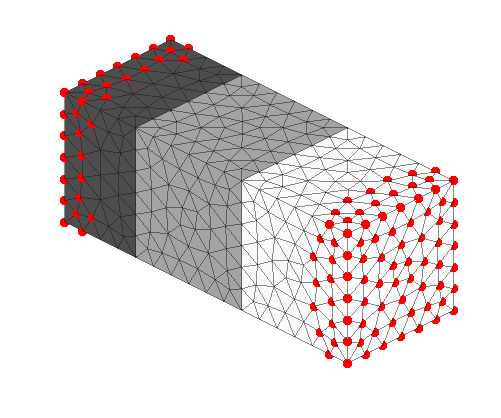

tolerance = 1;
markerSize = 15;
plane = 'x';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

clearvars

## Example 2

### Load mesh

Let's load the mesh data from "mesh_data_6.mat"

load("mesh_data_6.mat")

We will see 3 variables in the workspace: vert, ele, tnum

Use function plotMeshes3d to plot 3d mesh.

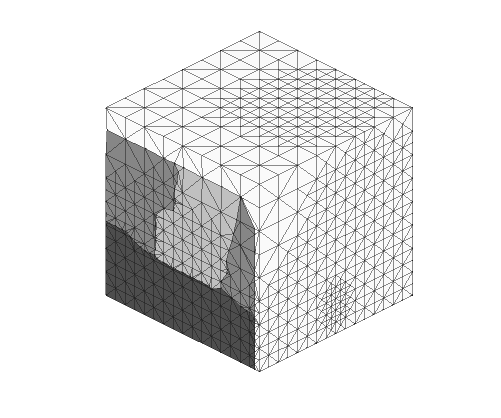

plotMeshes3d( vert, ele, tnum );

### Display boundary nodes

Before running function printInp3d, we can use function displayBCNode3d to check whether those boundary nodes have been correctly found. 

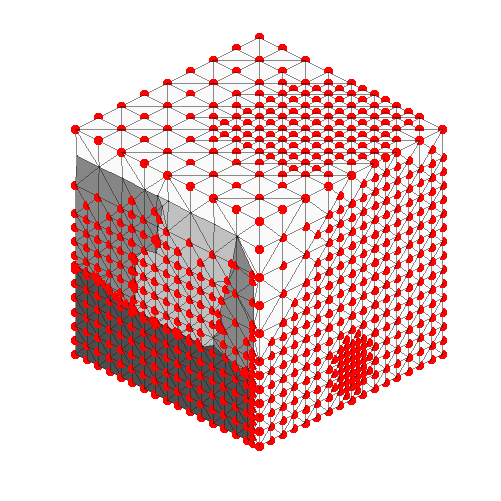

tolerance = 1E-10;
markerSize = 15;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

We noticed that some nodes are missing. So we can try a bigger tolerance.

### Change 'tolerance'

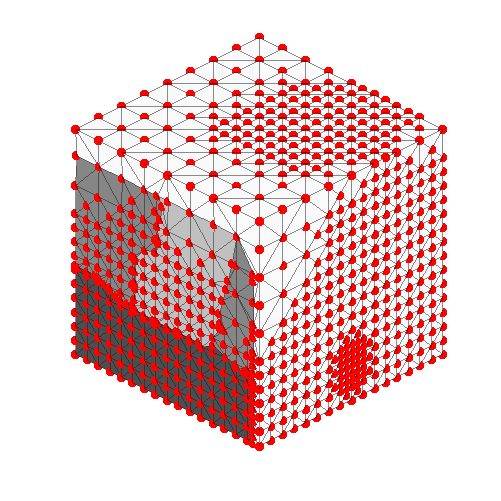

tolerance = 0.2;
markerSize = 15;
plane = 'all';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

Awesome. It's much better.

### Display node at 'x' boundary

To further validate the result, we can display boundary nodes at x min and x max.

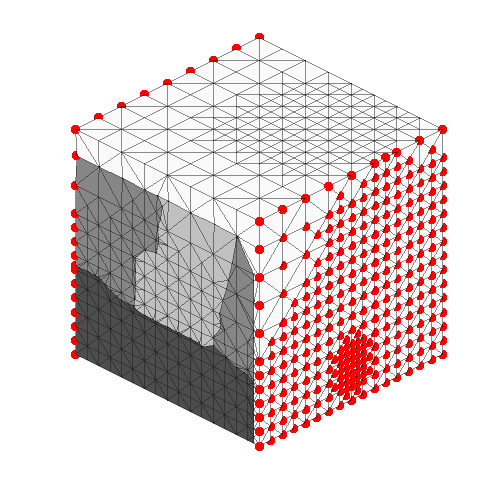

tolerance = 0.2;
markerSize = 15;
plane = 'x';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Display node at 'y' boundary

To further validate the result, we can display boundary nodes at y min and y max.

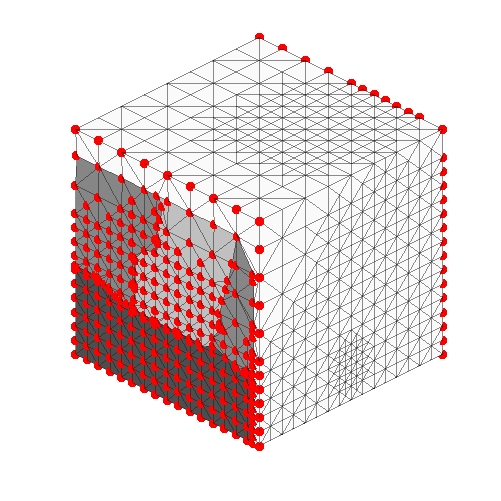

tolerance = 0.2;
markerSize = 15;
plane = 'y';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Display node at 'z' boundary

To further validate the result, we can display boundary nodes at z min and z max.

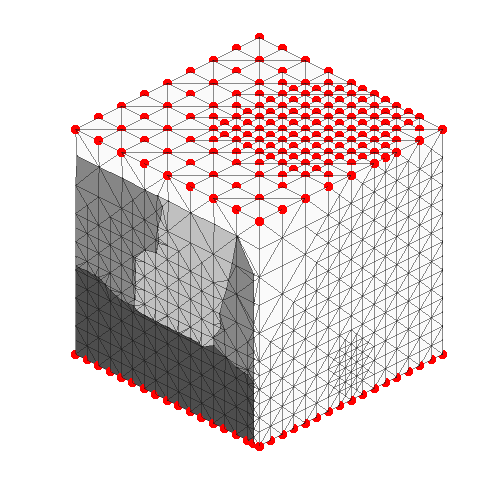

tolerance = 0.2;
markerSize = 15;
plane = 'z';
displayBCNode3d( vert, ele, tnum, tolerance, markerSize, plane );

### Export as inp file (Abaqus)

When using function printInp3d, we can specify 'opt.tolerance' explicitly. 

Default value of 'opt.tolerance' is 1E-10

ele_type = 'C3D4';
precision = 8;
file_name = 'test_2.inp';
opt = [];
opt.tolerance = 0.2;

printInp3d( vert, ele, tnum, ele_type, precision, file_name, opt );

printInp3d Done! Check the inp file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo